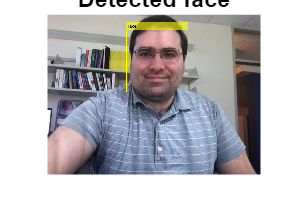

% CAMShift
% 1. Make a sensor to get face to track

% Make a cascade detector object.
faceSensor = vision.CascadeObjectDetector();

% Capture a video frame and run the face detector.
readFileVideo = VideoReader('tilted_face.avi');
frameOfVideo  = readFrame(readFileVideo);
boundingFrame          = step(faceSensor, frameOfVideo);

% Draw the returned bounding box around the detected face.
outputVideo = insertObjectAnnotation(frameOfVideo,'rectangle',boundingFrame,'Face');
figure, imshow(outputVideo), title('Detected face');


% 2. Using skin tone as the feature for tracking

% Retrieve the skin tone data by extracting the Hue component from the video frame that has been converted to the HSV color space.
[hueChannel,~,~] = rgb2hsv(frameOfVideo);

% Show the Hue Channel data and draw the bounding box around
% the face.
figure, imshow(hueChannel), title('Hue channel data');
rectangle('Position',boundingFrame(1,:),'LineWidth',2,'EdgeColor',[1 1 0])

% 3. Tracking the face

% Identify the nose within the face. The nose serves as a more
% precise indicator of the skin tone as it excludes any pixels
% from the background.

noseSensor = vision.CascadeObjectDetector('Nose', 'UseROI', true);
noseBoundingFrame     = step(noseSensor, frameOfVideo, boundingFrame(1,:));

% Make the tracking object.
tracking = vision.HistogramBasedTracker;

% Set up the tracker histogram by utilising the pixels from 
% the Hue channel specifically from the nose area.
initializeObject(tracking, hueChannel, noseBoundingFrame(1,:));

% Instantiate a video player object to showcase and
% visualise video frames.
videoPlayer  = vision.VideoPlayer;

% Continuously monitor and track the face across consecutive
% video frames until the entire video has ended.
while hasFrame(readFileVideo)
    
    % Retrieve the subsequent video frame
    frameOfVideo = readFrame(readFileVideo);
    
    % RGB -> HSV
    [hueChannel,~,~] = rgb2hsv(frameOfVideo);
    
    % Monitor using the Hue channel data
    boundingFrame = step(tracking, hueChannel);
    
    % Apply a bounding box around the person that is currently being tracked.
    outputVideo = insertObjectAnnotation(frameOfVideo,'rectangle',boundingFrame,'Face');    
    
    % Show the annotated video frame by utilising the video player object.
    step(videoPlayer, outputVideo);
    
end

% Release resources
release(videoPlayer);
